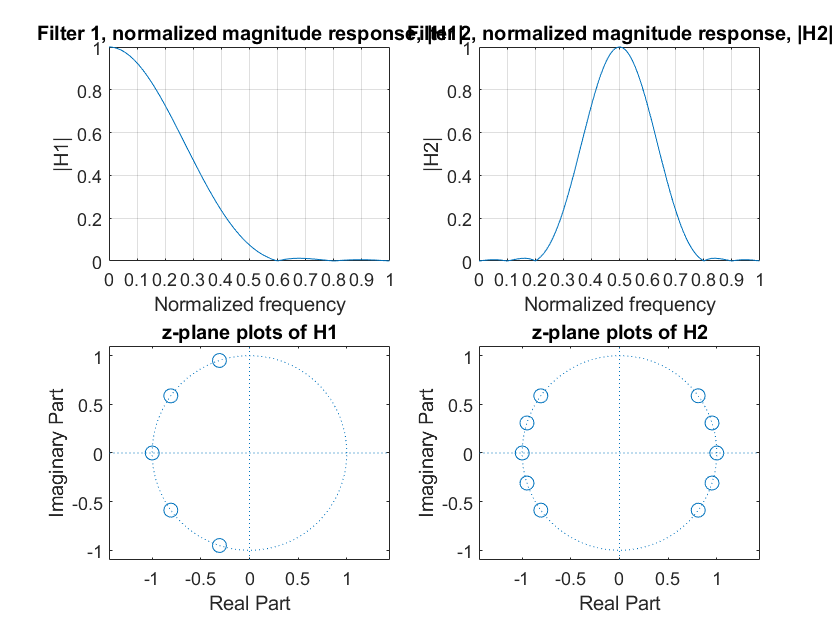

 
% zpart4.m clear; close all; 
N = 1024;  
%Filter 1 
Z1_ang = [ -1 0.8 -0.8 0.6 -0.6]*pi; %Denormalized with pi 
Z1=cos(Z1_ang)+j*sin(Z1_ang);% Z1 = ??? %Use formula cosө + jsinө 
h1 = poly(Z1); %Use poly function %To find the coefficients of the characteristic polynomial of a matrix Z1 
[H1, W1] = freqz(h1, N); 
H1 = H1 / max(abs(H1)); 
n1 = [0:length(h1)-1];

%Filter 1 
Z2_ang=[0  0.1 -0.1  0.2 -0.2 1 0.8 -0.8 0.9 -0.9]*pi;
Z2=cos(Z2_ang)+j*sin(Z2_ang);
h2 = poly(Z2);
[H2, W2] = freqz(h2, N); 
H2 = H2 / max(abs(H2)); 
n2 = [0:length(h2)-1];

%Plottings figure; 
% %Filter 1
subplot(2,2,1); 
plot(W1/pi, abs(H1)); 
set(gca,'xtick',[0:0.1:1]); 
grid on; 
title('Filter 1, normalized magnitude response, |H1|'); 
xlabel('Normalized frequency');  
ylabel('|H1|');
subplot(2,2,3);  
zplane(Z1', []);  
title('z-plane plots of H1'); 

% %Filter 1
subplot(2,2,2); 
plot(W2/pi, abs(H2)); 
set(gca,'xtick',[0:0.1:1]); 
grid on; 
title('Filter 2, normalized magnitude response, |H2|'); 
xlabel('Normalized frequency');  
ylabel('|H2|');
subplot(2,2,4); 
zplane(Z2', []);  
title('z-plane plots of H2');